# Assignment 2: Unsteady Convection transport

## Problem definition

Consider the governing transient convection equation with homogeneous Dirichlet conditions on the inflow boundary and linear convective term:


$$\begin{cases}\displaystyle \frac{\partial u}{\partial t}+ \nabla\cdot(\mathbf{a}u)=s(\mathbf{x},t) & \textrm{in} \ \Omega\times]0,T[ \\
u(\mathbf{x},0)=u_0(\mathbf{x}) & \textrm{on} \ \Omega \ \textrm{at} \ t=0 \\
u=0 & \textrm{on} \ \Gamma^{in}\times]0,T[
\end{cases}$$


Consider a square domain [-0.5, 0.5] x [-0.5, 0.5] with 20x20 elements and:

- Initial condition is a product-cosine hill centered in (1/6,1/6).

- Convective velocity is **a**(x,y)=(-y,x).

- Null source term.

Since the convection velocity is divergence-free the problem can be rewritten as


$$\begin{cases}\displaystyle \frac{\partial u}{\partial t}+ (\mathbf{a}\cdot\nabla)u=0 & \textrm{in} \ \Omega\times]0,T[ \\
u(\mathbf{x},0)=u_0(\mathbf{x}) & \textrm{on} \ \Omega \ \textrm{at} \ t=0 \\
u=0 & \textrm{on} \ \Gamma^{in}\times]0,T[
\end{cases}$$


The main feature of this equation is that space and time are linked by the characteristics. To compute a numerical solution, a double discretization has to be performed (in space and in time) and to obtain accurate solutions it cannot be done anyhow.

Spatial discretization is performed first using linear finite elements.

Then, transient response is computed using a time-stepping algorithm.

The following methods can be used to solve the problem:

[1]: TG2          Galerkin formulation + Lax-Wendroff method with consistent mass matrix

[2]: LW-FD        Galerkin formulation + Lax-Wendroff method with lumped mass matrix

[3]: TG3          Galerkin formulation + third-order explicit Taylor-Galerkin method

[4]: CN           Galerkin formulation + Crank-Nicolson with consistent mass matrix

[5]: CN-FD        Galerkin formulation + Crank-Nicolson with lumped mass matrix

[6]: CJ           Least-squares formulation + Crank-Nicolson method (Carey-Jiang)

[7]: TG3-2S       Galerkin formulation + third order two-step Taylor-Galerkin method

## Running the code

To solve our problem we need to call the class 'UnsteadyConvectionTests'. Previously, we need to gather some properties. Since a lot of variables are fixed, in this case we just need to define:

1. The time-stepping method, selecting a number from 1 to 7 (see list depicted just at the end of the Introduction section). For instance, the number [1] correspond to the TG2 method:

s.method = 1;

2. Number of revolutions of the rotating cone. Consider a single revolution (2pi rad):

s.revolutions = 1;

3. Number of time steps. For instance:

s.timeSteps = 120;

Thus,

probM1 = UnsteadyConvectionProblem(s);
u      = probM1.compute();

Finally, we can plot the surface and contour lines of the solution at some time step. For example, at the last time step:

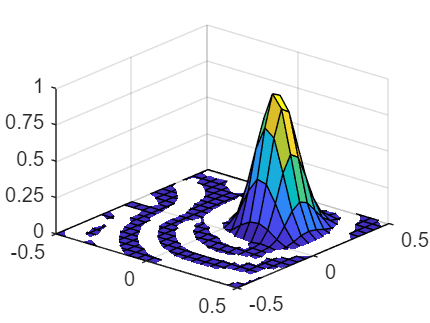

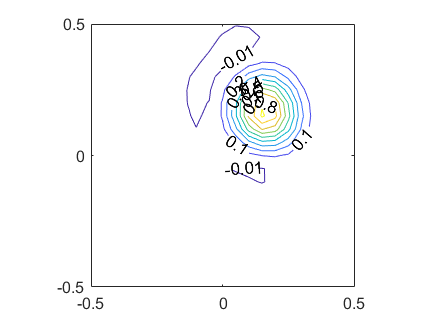

nLast = size(u,2);
probM1.plot(u,nLast);

## Questions

**1. Using the same number of revolutions and time steps as in previous section, plot the solution at the final time step for the remaining 6 methods. Explain the general differences and which one provides the worst behavior and why.**

Write here your answer.

**2. Prepare a function which, given a general coordinate (x,y) and the time step increment dt, computes the characteristic curve associated to the convective velocity. The output should be some matrix of the form '(Time) x (X,Y)' (not to confuse with the coordinate matrix of the mesh). Use the function several times for different (x,y) and obtain a contour plot of the convective velocity.**

Write here your answer.

**3. Prepare a function which, given the complete solution u, a mesh coordinate j and a time step k, plots the transient evolution of the particle that at instant t_k was in position (x_k,y_j). Use the function for some coordinates and time steps to validate it. Hint: you may use at some point the function coded from previous question.**

Write here your answer.

**4. Using the function coded from previous question, plot the transient evolution of the cosine hill top. Compare all methods and explain the linkage with the source term and the characteristic lines. What trajectory is the hill following?**

Write here your answer.

**5. If you try to compute the solution with a few number of time steps, for instance 10, you will get an error because the time step was too large. Explain why are you getting this error and compute the minimum number of time steps needed, based on your criteria.**

Write here your answer.

## **Auxiliar functions definition**

% Code here any function you will use in this script

